# Second Order System Approximation : Task 5.3

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.




M_p = 2 % Max overshoot in percent

M_p =      2


t_r = 0.01 % Rise Time 10-90 percent

t_r =    1.0000e-02



zeta = 0.6*(1- (M_p/100))

zeta =    5.8800e-01


omega_n = 1.8/t_r

omega_n =    180



Hcl = (omega_n^2)/(s^2 + 2*zeta*omega_n*s + omega_n^2)

Hcl =
 
          32400
  ---------------------
  s^2 + 211.7 s + 32400
 
Continuous-time transfer function.




isstable(Hcl)

ans = logical
   1



pole(Hcl)

syscl = ss(Hcl)

syscl =
 
  A = 
           x1      x2
   x1  -211.7  -253.1
   x2     128       0
 
  B = 
       u1
   x1  16
   x2   0
 
  C = 
          x1     x2
   y1      0  15.82
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.





p1 = -4.5

p1 =   -4.5000e+00


p2_1 = -2*zeta*omega_n - p1 

p2_1 =   -2.0718e+02


p2_2 = omega_n^2 / p1

p2_2 =        -7200


p2 = max( p2_1 , p2_2)

p2 =   -2.0718e+02




syscl_2 = p1*p2/((s - p1)*(s - p2))

syscl_2 =
 
          932.3
  ---------------------
  s^2 + 211.7 s + 932.3
 
Continuous-time transfer function.



pole(syscl_2)

ans =   -2.0718e+02
  -4.5000e+00



isstable(syscl_2)

ans = logical
   1


stepinfo(syscl_2)

ans = struct with fields:
        RiseTime: 4.8831e-01
    SettlingTime: 8.7428e-01
     SettlingMin: 9.0238e-01
     SettlingMax: 9.9932e-01
       Overshoot: 0
      Undershoot: 0
            Peak: 9.9932e-01
        PeakTime: 1.6272e+00


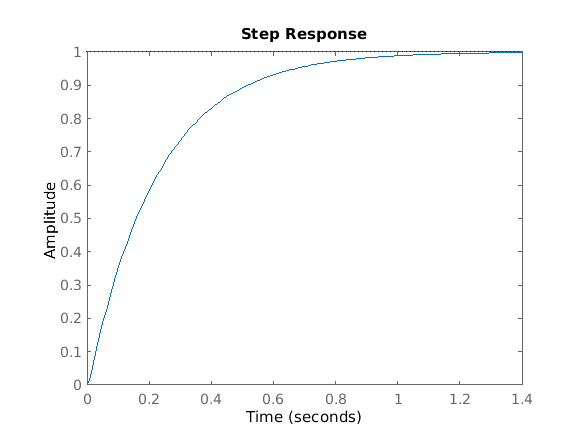

step(syscl_2)

stepinfo(Hcl)

ans = struct with fields:
        RiseTime: 1.0149e-02
    SettlingTime: 3.2887e-02
     SettlingMin: 9.0855e-01
     SettlingMax: 1.1018e+00
       Overshoot: 1.0185e+01
      Undershoot: 0
            Peak: 1.1018e+00
        PeakTime: 2.1755e-02


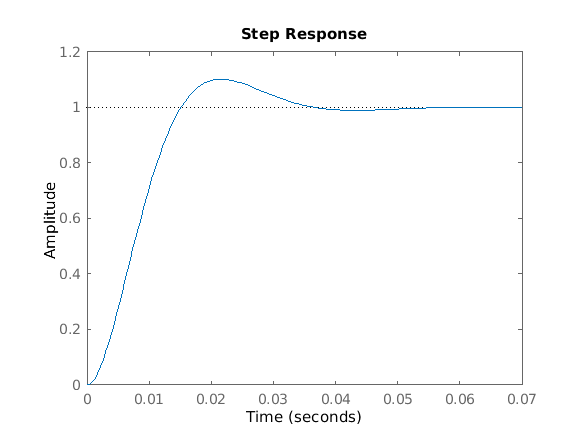

step(Hcl)

% K= place(syscl.A, B, P)



p1 = -4

p1 =     -4


p2 = -1

p2 =     -1




syscl3 = p1*p2/((s - p1)*(s - p2))

syscl3 =
 
        4
  -------------
  s^2 + 5 s + 4
 
Continuous-time transfer function.



pole(syscl3)

ans =     -4
    -1



isstable(syscl3)

ans = logical
   1


stepinfo(syscl3)

ans = struct with fields:
        RiseTime: 2.3121e+00
    SettlingTime: 4.1998e+00
     SettlingMin: 9.0117e-01
     SettlingMax: 9.9892e-01
       Overshoot: 0
      Undershoot: 0
            Peak: 9.9892e-01
        PeakTime: 7.1150e+00


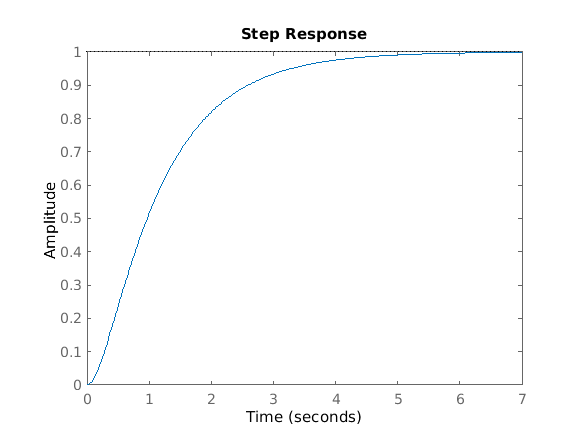

step(syscl3)


omega_n = sqrt(p1*p2)

omega_n =      2


zeta = -(p1 + p2)/(2*omega_n)

zeta =    1.2500e+00



t_r = 1.8/omega_n

t_r =    9.0000e-01


Scaling Factor:

Acl= A-B*K

Acl =             0   1.0000e+00            0            0
   1.6350e+03   2.5643e+03   4.8114e+03   8.0106e+02
            0            0            0   1.0000e+00
  -7.0010e+03  -1.0980e+04  -2.0567e+04  -3.4300e+03


Ecl= eig(Acl)

Ecl =   -8.4340e+02
  -1.5925e+01
  -7.5351e-01
  -5.6422e+00


Step Response:

syscl= ss(Acl, B, C, D)

syscl =
 
  A = 
               x1          x2          x3          x4
   x1           0           1           0           0
   x2        1635        2564        4811       801.1
   x3           0           0           0           1
   x4       -7001  -1.098e+04  -2.057e+04       -3430
 
  B = 
           u1
   x1       0
   x2    36.6
   x3       0
   x4  -156.7
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



s = tf('s')

s =
 
  s
 
Continuous-time transfer function.




kP = 1

kP =      1


kI = 1

kI =      1


kD = 1

kD =      1



G_PID = kP + kI/s + kD*s

G_PID =
 
  s^2 + s + 1
  -----------
       s
 
Continuous-time transfer function.

